# Spotting Swing Model

%[theta d a alpha sigma offset]
%theta [rad] angle of joint
%d length of prismatic componet
%a length of link
% alpha [rad] link twist angle
% sigma == 1 is prismatic  == 0 is revolute
%offset
link1 = Link( [ deg2rad(74.311), 0, 17.917, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [74.311-2 74.311+2];

link1 = Link( [ deg2rad(0), 0, 17.917, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [0-2 0+2];

link2 = Link( [ deg2rad(0), 0, 13.75, 0, 0, 0], 'standard' );
link2.qlim = pi/180 * [-2 2];

link2A = Link( [ 0, 0, 0, deg2rad(90), 0, 0], 'standard');
link2A.qlim = pi/180 * [-5 5];

link3 = Link( [           deg2rad(0), 0,     0, 0, 1, 0], 'standard' );
link3.qlim = [0 4.75];

modelMasterX = SerialLink( [link1, link2, link2A, link3], 'name', 'masterX')

 
modelMasterX = 
 
masterX:: 4 axis, RRRP, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|     17.917|          0|          0|
|  2|         q2|          0|      13.75|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|          0|         q4|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%inputs forward kinematics
spottingSWGCylinderExtension = 4.75/2 %limit is 0 to 4.75

spottingSWGCylinderExtension = 2.3750

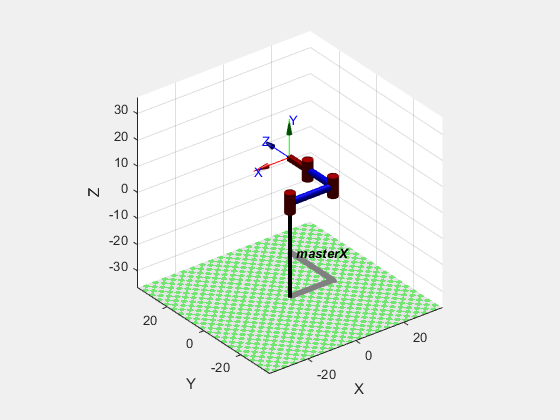

Tmaster = [deg2rad(0), deg2rad(90), deg2rad(90),10];%spottingSWGCylinderExtension ];
modelMasterX.plot(Tmaster)


%input inverse kinematic
masterHoleX = 9%8.842

masterHoleX = 9

%angles look to be between 10 and -10 degrees, inclinometers are not set up to report negative angles so it will be in range of (180, 360)
gunAngle = 5; 
gunHeight = 6.9642 * cos( deg2rad( 21.0375 + gunAngle ) )

gunHeight = 6.2574

%angles look to be between 10 and -10 degrees, inclinometers are not set up to report negative angles so it will be in range of (180, 360)
guidewheelAngle = 354;
guidewheelAngle = 355-360;
guidewheelHeight = 17.917 * sin( deg2rad( guidewheelAngle + 88.6659) )

guidewheelHeight = 17.8076

height = gunHeight + guidewheelHeight

height = 24.0650

x = 38.189 * cos( deg2rad( 89.5304 + gunAngle ) )

x = -3.0165

xoffset = 17.917 * sin( deg2rad( guidewheelAngle ) ) + 6.9642 * sin( deg2rad( 21.0375 + gunAngle ) )

xoffset = 1.4954

spottingSWGCylinderExtension = sqrt(masterHoleX * masterHoleX + height * height) - link2.a - xoffset + x

spottingSWGCylinderExtension = 7.4310

Tmaster = [deg2rad(0), deg2rad(90), deg2rad(90),spottingSWGCylinderExtension ];
modelMasterX.plot(Tmaster)

Error using SerialLink/plot (line 206)
Insufficient columns in q

# Pattern Swing Model

%L1 = Link ([0 l1 0 pi/2],'standard');
%L1.isrevolute
%L1.qlim =  pi/180*[-180 18

%[theta d a alpha sigma offset]
%sigma == 1, prismatic
%sigma == 0, revolute
link1 = Link( [ deg2rad(0), 0, 32.75, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [-60 60];

link2 = Link( [ deg2rad(-90), 0, 20.25, 0, 0, 0], 'standard' );
link2.qlim = pi/180 * [-95 85];
%39.486
link3 = Link( [ deg2rad( 0), 0, 0, 0, 1, 0], 'standard' );
link3.qlim = [ 0 9.5];

link4 = Link( [ deg2rad(0), 0, 32.75, 0, 0, 0], 'standard' );
link4.qlim = pi/180 * [ -60 60];


modelSlaveX = SerialLink( [link1, link2, link3, link4], 'name', 'slaveX')
%inputs forward kinematics
patternSWGCylinderExtension = 9.5/2 %limit is 0 to 9.5
Tslave = [ deg2rad( 0 ), deg2rad(-90), patternSWGCylinderExtension, deg2rad( -90 )];
modelSlaveX.plot(Tslave)

%input inverse kinematic
slaveHoleX = 23
version = 1;
height = 38.188 * cos( deg2rad( 70 ))
if version == 1
    patternSWGCylinderExtension = sqrt( slaveHoleX * slaveHoleX + height*height ) - link2.a
else
    carriageToGun = 7.061;
    carriageToSpottingCylinder = 0.313;
    patternSWGCylinderExtension = slaveHoleX - link2.a - masterHoleX + carriageToGun+(carriageToGun-carriageToSpottingCylinder)
end

Tslave = [ deg2rad( 0 ), deg2rad(-90), patternSWGCylinderExtension, deg2rad( -90 )];
modelSlaveX.plot(Tslave)